clear data
clear fittdata
%curve fitting TTC data

%tire in question is Hoosier 18.0 x 6.0 - 10  R25B
%Using round 5 ttc data
%SI units will be used

%contents round 5.pdf has a general guide
%runguide_round5.pdf has tables used to identify tires

%file:///C:/Users/lwitten/Downloads/TIRE%20ANALYSIS%20AND%20MODELLING%20FOR%20THE%20DEVELOPMENT%20OF%20AN%20FSAE%20CAR%20(1).pdf
%helpful analysis paper, page 53

%here's what their machine can do/ sweep through


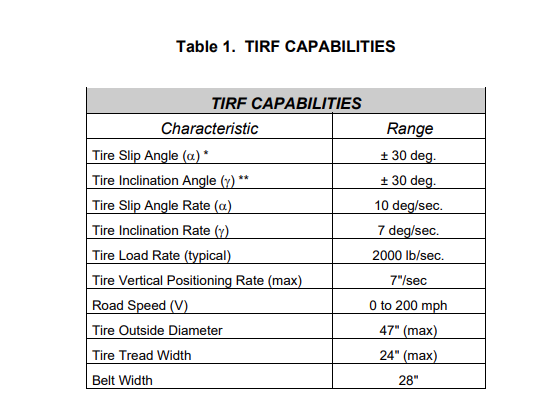



%tire being analyzed = 1464tire19 (cornering), 1464tire21 (braking)
%Hoosier 18.0 x 6.0 - 10  R25B
%10 in rim dia, 6 in rim width
%represented by runs 18,19 for cornering. runs 36,37 and 35* for
%drive/brake/combined

%pretest weight = 8.075lb

%cornering first. lets analyze run 19 specifically

%data from cornering stiffness table


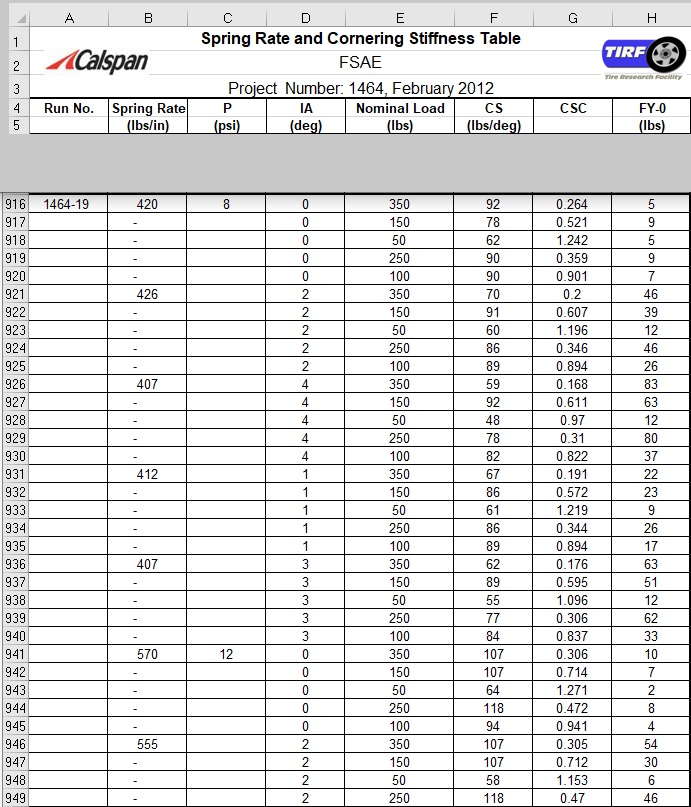

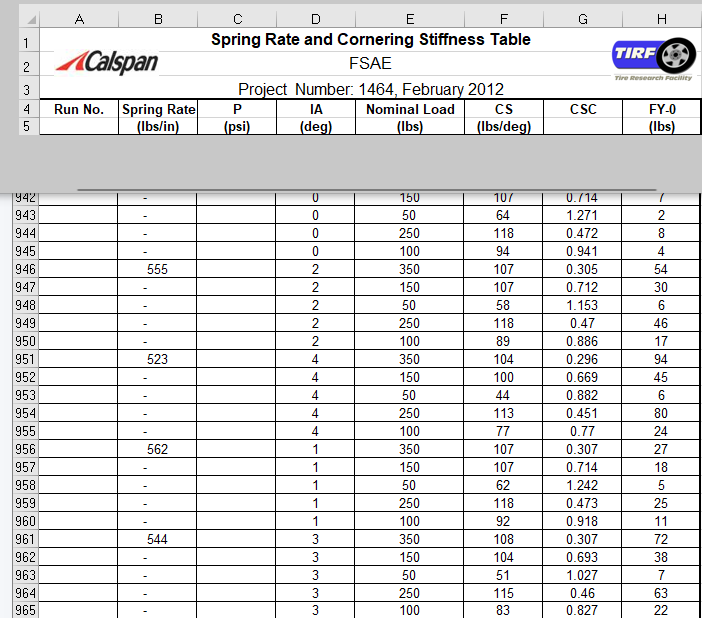

Data is from the run 19 file

%lets start separating out data

%first split by pressures, they seem to split at about second 905
%finding the index
[d, ix] = min(abs( ET - 905))

d = 0.7990

ix = 27676

% separate out lists by pressure

%naming scheme
% var_runNo._pressurekPa_IAdegrees_FzNewtons

%list of lists i care about
list_of_listnames=["ET","FY","FZ","IA","P","SA"];

data.r19.ET.kpa55 = ET(1:ix);
data.r19.ET.kpa83 = ET(ix+1:end);
data.r19.FY.kpa55 = FY(1:ix);
data.r19.FY.kpa83 = FY(ix+1:end);
data.r19.FZ.kpa55 = FZ(1:ix);
data.r19.FZ.kpa83 = FZ(ix+1:end);
data.r19.IA.kpa55 = IA(1:ix);
data.r19.IA.kpa83 = IA(ix+1:end);
data.r19.P.kpa55 = P(1:ix);
data.r19.P.kpa83 = P(ix+1:end);
data.r19.SA.kpa55 = SA(1:ix);
data.r19.SA.kpa83 = SA(ix+1:end);

max(data.r19.FY.kpa55)

ans = 2.6874e+03

max(data.r19.FY.kpa83)

ans = 3.1907e+03

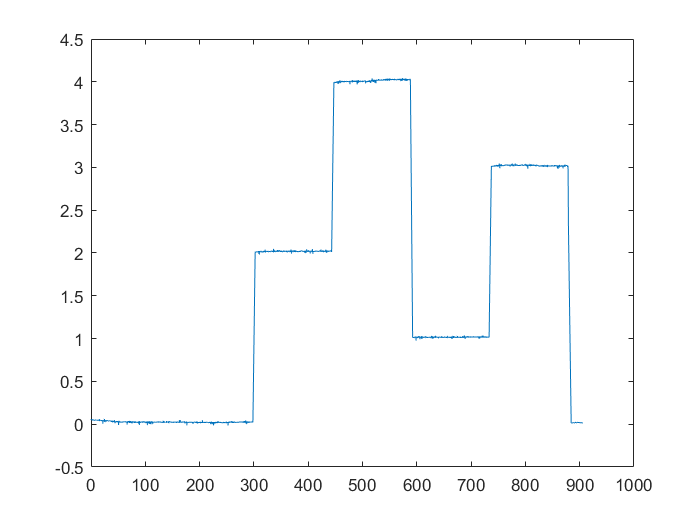


plot(data.r19.ET.kpa55,data.r19.IA.kpa55)


%separate out inclination angle runs visually
%actually don't need to retain pressure or IA data after separation
%done in a bad way here, done better later

[d, ix] = min(abs( data.r19.ET.kpa55 - 300));
[d, ix1] = min(abs( data.r19.ET.kpa55 - 443));
[d, ix2] = min(abs( data.r19.ET.kpa55 - 588));
[d, ix3] = min(abs( data.r19.ET.kpa55 - 728));
[d, ix4] = min(abs( data.r19.ET.kpa55 - 873));

data.r19.ET.kpa55d0 = data.r19.ET.kpa55(1:ix);
data.r19.ET.kpa55d2 = data.r19.ET.kpa55(ix+1:ix1);
data.r19.ET.kpa55d4 = data.r19.ET.kpa55(ix1+1:ix2);
data.r19.ET.kpa55d1 = data.r19.ET.kpa55(ix2+1:ix3);
data.r19.ET.kpa55d3 = data.r19.ET.kpa55(ix3+1:ix4);

data.r19.FY.kpa55d0 = data.r19.FY.kpa55(1:ix);
data.r19.FY.kpa55d2 = data.r19.FY.kpa55(ix+1:ix1);
data.r19.FY.kpa55d4 = data.r19.FY.kpa55(ix1+1:ix2);
data.r19.FY.kpa55d1 = data.r19.FY.kpa55(ix2+1:ix3);
data.r19.FY.kpa55d3 = data.r19.FY.kpa55(ix3+1:ix4);

data.r19.FZ.kpa55d0 = data.r19.FZ.kpa55(1:ix);
data.r19.FZ.kpa55d2 = data.r19.FZ.kpa55(ix+1:ix1);
data.r19.FZ.kpa55d4 = data.r19.FZ.kpa55(ix1+1:ix2);
data.r19.FZ.kpa55d1 = data.r19.FZ.kpa55(ix2+1:ix3);
data.r19.FZ.kpa55d3 = data.r19.FZ.kpa55(ix3+1:ix4);

data.r19.SA.kpa55d0 = data.r19.SA.kpa55(1:ix);
data.r19.SA.kpa55d2 = data.r19.SA.kpa55(ix+1:ix1);
data.r19.SA.kpa55d4 = data.r19.SA.kpa55(ix1+1:ix2);
data.r19.SA.kpa55d1 = data.r19.SA.kpa55(ix2+1:ix3);
data.r19.SA.kpa55d3 = data.r19.SA.kpa55(ix3+1:ix4);

%157 visually identified as end of startup period on d0, unique
[d, ix5] = min(abs( data.r19.ET.kpa55 - 157))

d = 0.3000

ix5 = 5401


data.r19.SA.kpa55d0 = data.r19.SA.kpa55(ix5:ix);
data.r19.FZ.kpa55d0 = data.r19.FZ.kpa55(ix5:ix);
data.r19.FY.kpa55d0 = data.r19.FY.kpa55(ix5:ix);
data.r19.ET.kpa55d0 = data.r19.ET.kpa55(ix5:ix);



%plots of slip angle vs lateral force for all cambers @ 55 kpa, various Fz
%plot(data.r19.SA.kpa55d0,data.r19.FY.kpa55d0)
%plot(data.r19.SA.kpa55d1,data.r19.FY.kpa55d1)
%plot(data.r19.SA.kpa55d2,data.r19.FY.kpa55d2)
%plot(data.r19.SA.kpa55d3,data.r19.FY.kpa55d3)
%plot(data.r19.SA.kpa55d4,data.r19.FY.kpa55d4)

max(data.r19.FY.kpa55d0)

ans = 2.1363e+03

max(data.r19.FY.kpa55d1)

ans = 2.1574e+03

max(data.r19.FY.kpa55d2)

ans = 2.4060e+03

max(data.r19.FY.kpa55d3)

ans = 2.5003e+03

max(data.r19.FY.kpa55d4)

ans = 2.6874e+03


clear ET FX FY FZ IA MX MZ N NFX NFY P RE RL RST SA SL SR TSTC TSTI TSTO V
data.r19.FY.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


data.r19.ET.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


data.r19.FZ.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


data.r19.IA.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


data.r19.P.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


data.r19.FX.kpa55 = NaN

data = struct with fields:
    r19: [1×1 struct]


SEPARATE KPA55 runs by SA/force

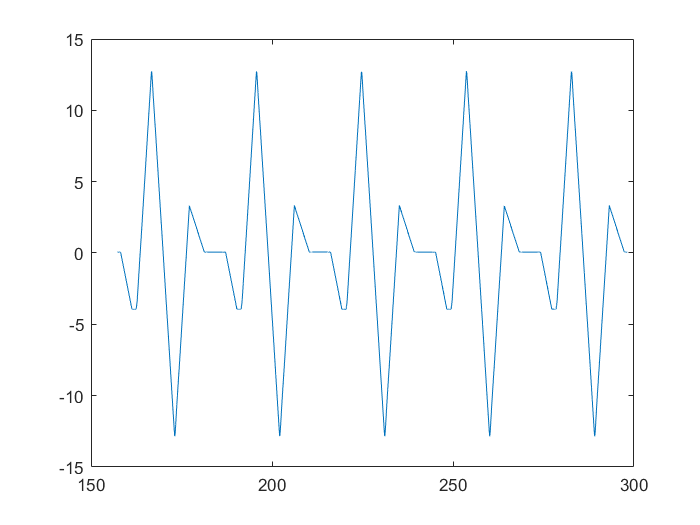

%186 214 245 274 for d0
plot(data.r19.ET.kpa55d0,data.r19.SA.kpa55d0)


[d, ix] = min(abs( data.r19.ET.kpa55d0 - 186))

d = 0.3000

ix = 886

[d, ix1] = min(abs( data.r19.ET.kpa55d0 - 214))

d = 1.3000

ix1 = 1771

[d, ix2] = min(abs( data.r19.ET.kpa55d0 - 245))

d = 0

ix2 = 2691

[d, ix3] = min(abs( data.r19.ET.kpa55d0 - 274))

d = 0

ix3 = 3576

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.kpa55d0)]

ixlist =            1         886         887        1771        1772        2691        2692        3576        3577        4425


%use for doing a ton of computations together
for p_index =1:1
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 1:1
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end


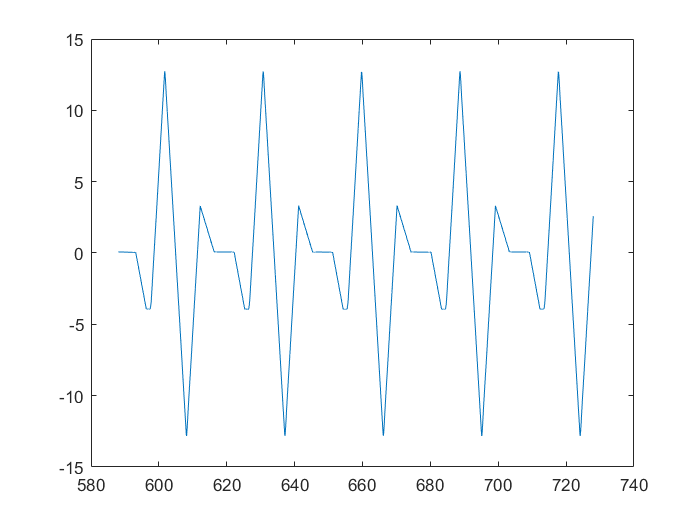

%617 646 674 703 for d1
plot(data.r19.ET.kpa55d1,data.r19.SA.kpa55d1)


[d, ix] = min(abs( data.r19.ET.kpa55d1 - 617))

d = 1.0000e-03

ix = 885

[d, ix1] = min(abs( data.r19.ET.kpa55d1 - 646))

d = 1.0000e-03

ix1 = 1770

[d, ix2] = min(abs( data.r19.ET.kpa55d1 - 674))

d = 0.2990

ix2 = 2620

[d, ix3] = min(abs( data.r19.ET.kpa55d1 - 703))

d = 0.2990

ix3 = 3505

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.kpa55d1)]

ixlist =            1         885         886        1770        1771        2620        2621        3505        3506        4380


%use for doing a ton of computations together
for p_index =1:1
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 2:2
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end


run_name_nof = "kpa55d2" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa55d2"

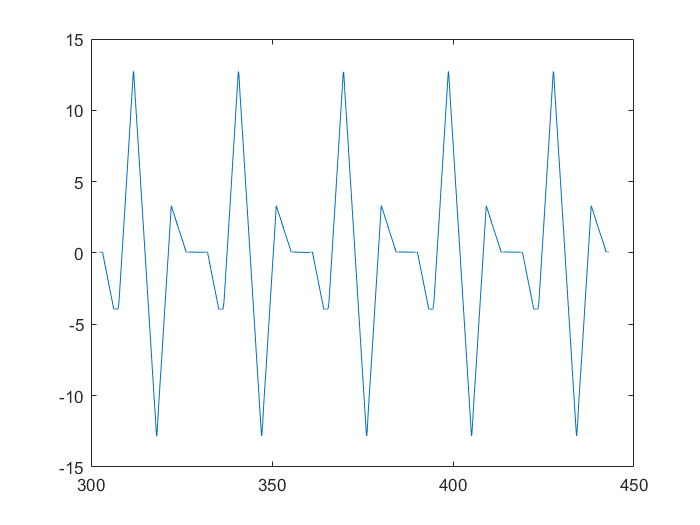


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))



[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 327))

d = 0

ix = 876

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 355))

d = 0.3000

ix1 = 1726

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 384))

d = 0.3000

ix2 = 2611

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 413))

d = 0.3000

ix3 = 3496

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         876         877        1726        1727        2611        2612        3496        3497        4416


%use for doing a ton of computations together
for p_index =1:1
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 3:3
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end


run_name_nof = "kpa55d3" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa55d3"

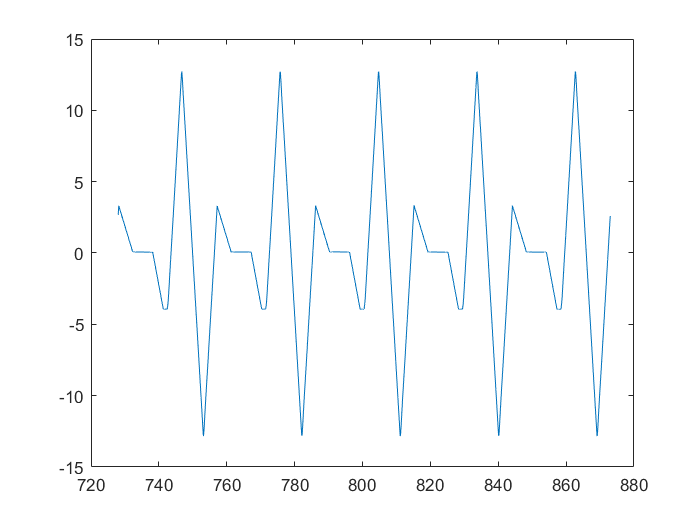


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 762))

d = 1.0000e-03

ix = 930

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 791))

d = 1.0000e-03

ix1 = 1815

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 819))

d = 0.2990

ix2 = 2665

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 849))

d = 1.0000e-03

ix3 = 3585

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         930         931        1815        1816        2665        2666        3585        3586        4425


%use for doing a ton of computations together
for p_index =1:1
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 4:4
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

run_name_nof = "kpa55d4" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa55d4"

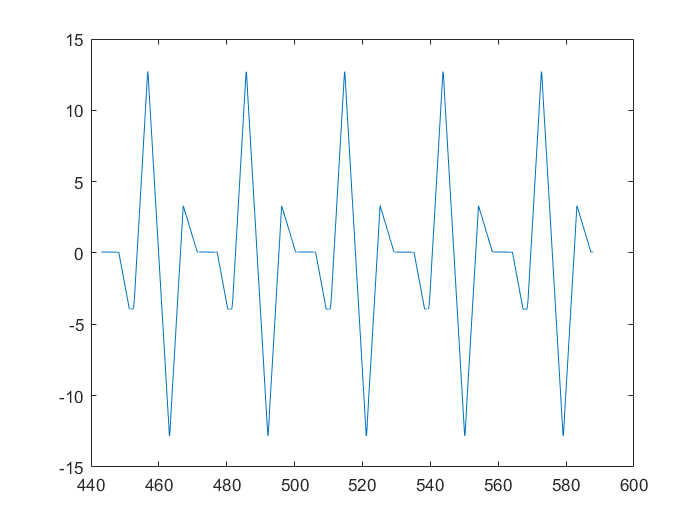


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


var = NaN %make the graph readable

var = NaN


[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 472))

d = 0

ix = 885

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 500))

d = 0.3000

ix1 = 1735

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 529))

d = 0.2990

ix2 = 2620

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 559))

d = 1.0000e-03

ix3 = 3540

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         885         886        1735        1736        2620        2621        3540        3541        4425


%use for doing a ton of computations together
for p_index =1:1
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 5:5
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

KPA 83 runs, separating out

%separate out kpa 83 runs

run_name_nof = "kpa83" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83"

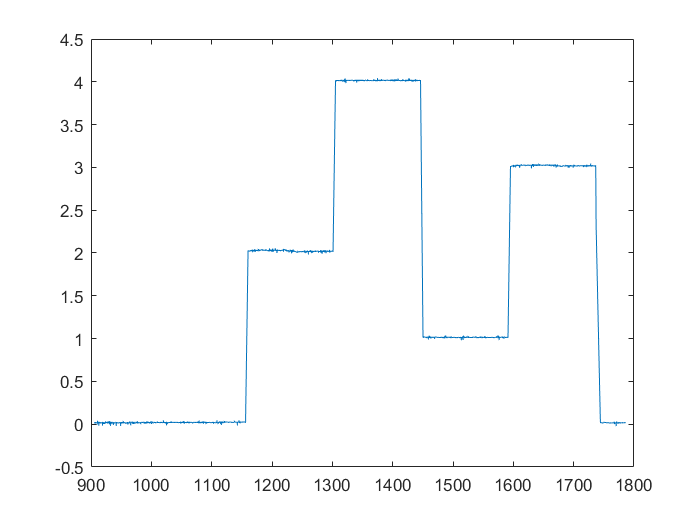


plot(data.r19.ET.(run_name_nof),data.r19.IA.(run_name_nof))

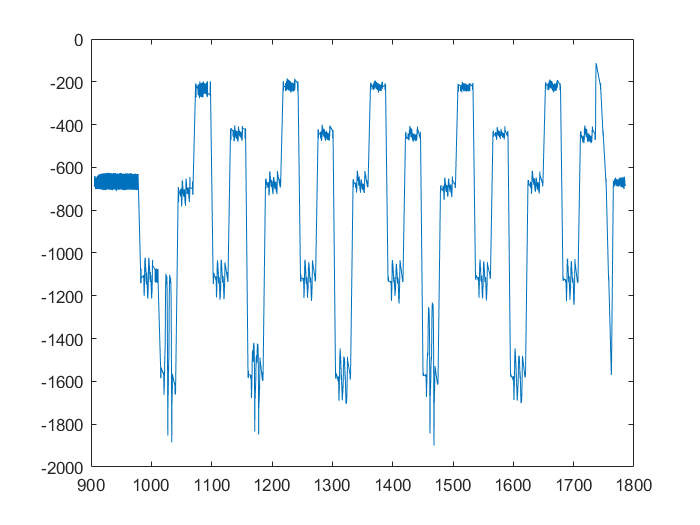

plot(data.r19.ET.(run_name_nof),data.r19.FZ.(run_name_nof))


[d, ix5] = min(abs( data.r19.ET.(run_name_nof) - 1014));%for beginning of first run

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1156));
[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1301));
[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1445));
[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1590));
[d, ix4] = min(abs( data.r19.ET.(run_name_nof) - 1736));
ixlist = [ix5,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,ix4];
%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];

    for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
        for camber_index = 1:5
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         

%changed to camber index here
lower_bound = ixlist(2*camber_index -1);
upper_bound = ixlist(2*camber_index);
%specific to kpa 83
data.r19.(var_name_list(var_index)).(run_name_nof) = data.r19.(var_name_list(var_index)).kpa83(lower_bound:upper_bound);

        end
        data.r19.(var_name_list(var_index)).kpa83 = NaN; % clear no longer necessary data

    end
end

run_name_nof = "kpa83d0" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83d0"

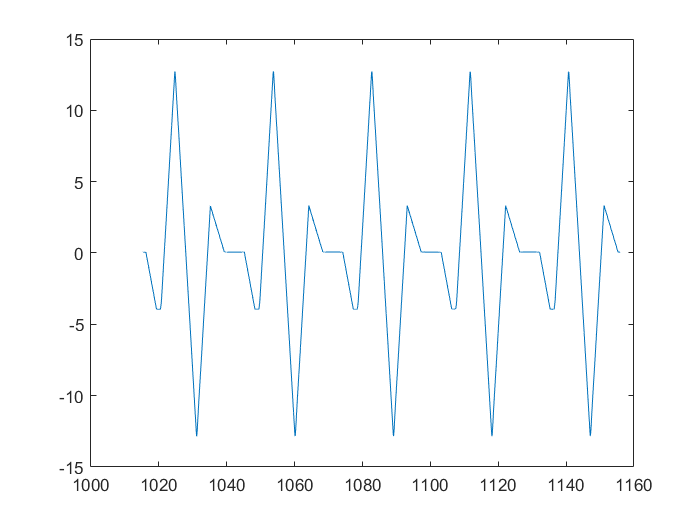


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


%plot([1,2],[1,2]) %make the graph readable

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1040))

d = 1.0000e-03

ix = 876

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1069))

d = 0.0020

ix1 = 1761

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1098))

d = 0.0030

ix2 = 2646

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1127))

d = 0.0040

ix3 = 3531

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         876         877        1761        1762        2646        2647        3531        3532        4416


%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 1:1
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

run_name_nof = "kpa83d2" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83d2"

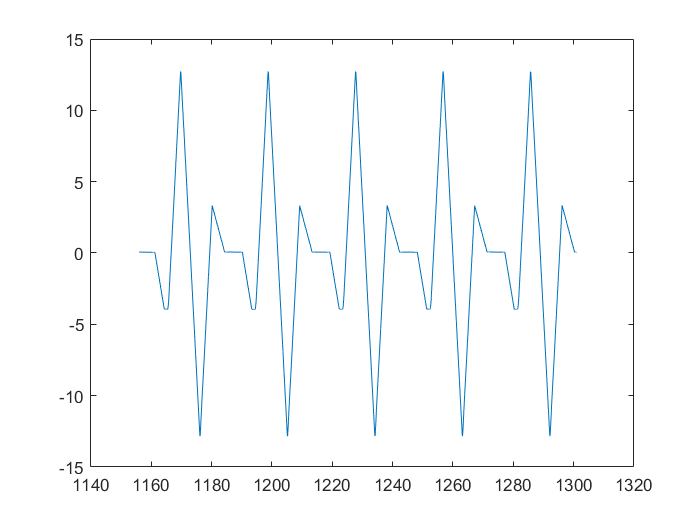


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


%plot([1,2],[1,2]) %make the graph readable

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1184))

d = 0.2950

ix = 850

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1213))

d = 0.2940

ix1 = 1735

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1242))

d = 0.2940

ix2 = 2620

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1272))

d = 0.0070

ix3 = 3540

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         850         851        1735        1736        2620        2621        3540        3541        4425


%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 2:2
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

run_name_nof = "kpa83d4" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83d4"

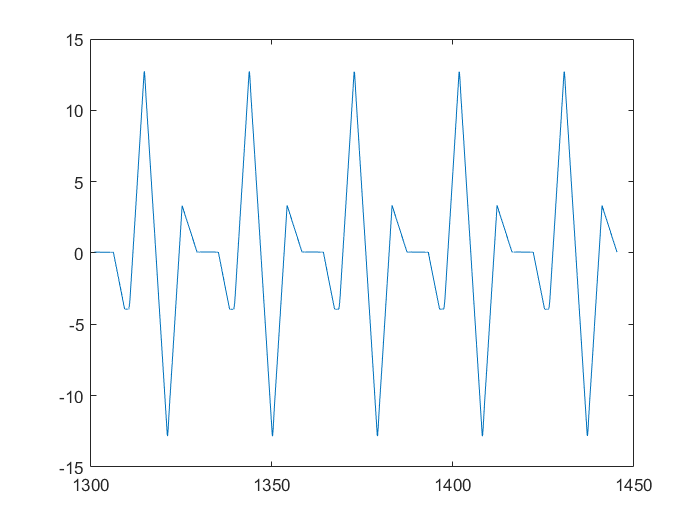


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


%plot([1,2],[1,2]) %make the graph readable

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1330))

d = 0.0090

ix = 885

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1358))

d = 0.2910

ix1 = 1735

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1387))

d = 0.2900

ix2 = 2620

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1416))

d = 0.2890

ix3 = 3505

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         885         886        1735        1736        2620        2621        3505        3506        4390


%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 3:3
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

run_name_nof = "kpa83d1" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83d1"

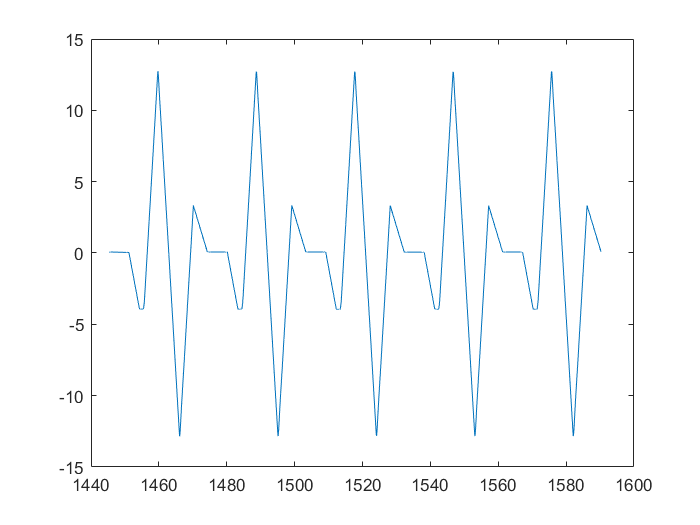


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


%plot([1,2],[1,2]) %make the graph readable

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1475))

d = 0.0080

ix = 921

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1504))

d = 0.0070

ix1 = 1806

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1533))

d = 0.0060

ix2 = 2691

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1562))

d = 0.0060

ix3 = 3576

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         921         922        1806        1807        2691        2692        3576        3577        4425


%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 4:4
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

run_name_nof = "kpa83d3" %added this for ease of moving, still have to change camber number below manually

run_name_nof = "kpa83d3"

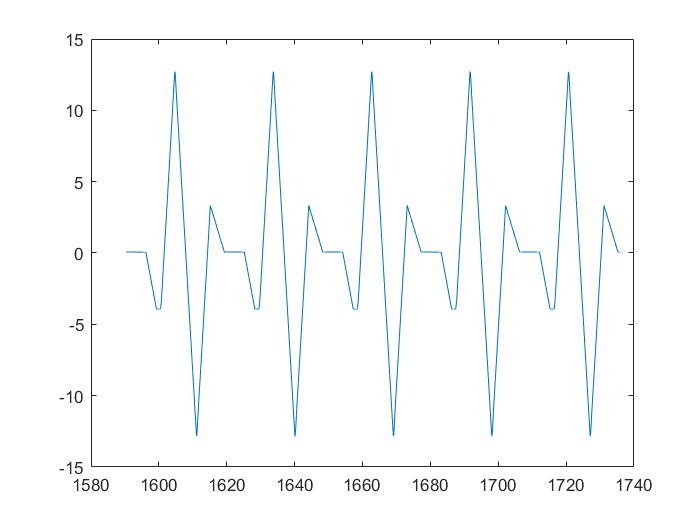


plot(data.r19.ET.(run_name_nof),data.r19.SA.(run_name_nof))


%plot([1,2],[1,2]) %make the graph readable

[d, ix] = min(abs( data.r19.ET.(run_name_nof) - 1620))

d = 0.0040

ix = 921

[d, ix1] = min(abs( data.r19.ET.(run_name_nof) - 1648))

d = 0.2840

ix1 = 1770

[d, ix2] = min(abs( data.r19.ET.(run_name_nof) - 1678))

d = 0.0030

ix2 = 2691

[d, ix3] = min(abs( data.r19.ET.(run_name_nof) - 1706))

d = 0.2820

ix3 = 3540

ixlist = [1,ix,ix+1,ix1,ix1+1,ix2,ix2+1,ix3,ix3+1,length(data.r19.ET.(run_name_nof))]

ixlist =            1         921         922        1770        1771        2691        2692        3540        3541        4461


%use for doing a ton of computations together
for p_index =2:2
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    for camber_index = 5:5
        camber_name_list = ["d0","d2","d4","d1","d3"];
        camber_list = [0,2,4,1,3];
        for var_index = 1:4
            var_name_list = ["ET","SA","FZ","FY","IA","P"];
            for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
run_name_nof = append(pressure_name_list(p_index),camber_name_list(camber_index));         
lower_bound = ixlist(2*force_index -1);
upper_bound = ixlist(2*force_index);
data.r19.(var_name_list(var_index)).(run_name) = data.r19.(var_name_list(var_index)).(run_name_nof)(lower_bound:upper_bound);
            end
        data.r19.(var_name_list(var_index)).(run_name_nof) = NaN; % clear no longer necessary data
        end
    end
end

Regression 

%global constants im defining that should never get changed ever

P0 = 60 %kpa

P0 = 60

FZ0 = 900 %newtons

FZ0 = 900

R0 = NaN %unloaded radius

R0 = NaN

Vref = NaN %reference forward velocity

Vref = NaN

%             baby regression 
%
% plot(data.r19.SA.kpa55d0lb350,data.r19.FY.kpa55d0lb350)
% %regress the data for one with respect to itself, cubic spline
% fit_sa_to_fy= csaps(data.r19.SA.kpa55d0lb350,data.r19.FY.kpa55d0lb350,.7);
% fnplt(fit_sa_to_fy)
% 
% offset = fnval(fit_sa_to_fy,0) %fy offset
% 
% data.r19.offset.kpa55d0lb350 = offset
% 
% fy_z0 = data.r19.FY.kpa55d0lb350 - offset %fy data with SA 0 = Fy 0
% 
% fit_sa_to_fy_z0  = csaps(data.r19.SA.kpa55d0lb350,fy_z0,.7) %new spline fit
% 
% %cornering stiffness, derivative at 0
% corn_stiff =  abs(fnval(fnder(fit_sa_to_fy_z0),0)) %eval derivative of curve fit at 0
% 
% SA_radians = data.r19.SA.kpa55d0lb350 .* pi/180
% 
% 
% max(fy_z0)
% 
% ft = fittype( 'D*sin(C*atan((B*k-E*(B*k-atan(k*B)))))', 'independent',...
% 'k', 'dependent', 'r' )
% opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
% opts.StartPoint = [0.118997681558377 0.498364051982143,2000,.2];
% fit_obj = fit(SA_radians,fy_z0,ft,opts)
% 
% coeffs = coeffvalues(fit_obj)
% 
% B = -6.266
% C = 1.598
% D = 2110
% E = -1.556
% plot(SA_radians,(D*sin(C*atan((B.*SA_radians -E*(B.*SA_radians-atan(SA_radians.*B)))))))
% 
% plot(data.r19.ET.kpa55d0lb350,data.r19.FZ.kpa55d0lb350)
% 
% 
% fittdata.kpa55d0lb350.B = coeffs(1);
% fittdata.kpa55d0lb350.C = coeffs(2);
% fittdata.kpa55d0lb350.D = coeffs(3);
% fittdata.kpa55d0lb350.E = coeffs(4);
% fittdata.kpa55d0lb350.camber = 0; %in degrees
% fittdata.kpa55d0lb350.dpi = (55 - P0)/P0;
% fittdata.kpa55d0lb350.P = 55;
% fittdata.kpa55d0lb350.Fz = 1556.8;
% fittdata.kpa55d0lb350.dfz = (1556.8 - FZ0)/FZ0;
% fittdata.kpa55d0lb350.offset = offset;
% fittdata.kpa55d0lb350.c_stiff = corn_stiff;

for p_index =1:2
    
    pressure_name_list = ["kpa55","kpa83"];
    pressure_list = [55,83];
    
    for camber_index = 1:5
        
        camber_name_list = ["d0","d1","d2","d3","d4"];
        camber_list = [0,1,2,3,4];

        
        for force_index = 1:5
            
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
            force_list = [1556.88,667.233,222.411,1112.06,444.822];
            
%perform regression steps for each run            

%find the name of the run in the database


run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));

%convert to radians
SA_radians = data.r19.SA.(run_name) .* pi/180;

fit_sa_to_fy= csaps(SA_radians,data.r19.FY.(run_name),.7);

offset = fnval(fit_sa_to_fy,0); %fy offset

fy_z0 = data.r19.FY.(run_name) - offset; %fy data with SA 0 = Fy 0

fit_sa_to_fy_z0  = csaps(data.r19.SA.(run_name),fy_z0,.7); %new spline fit

%cornering stiffness, derivative at 0
corn_stiff =  abs(fnval(fnder(fit_sa_to_fy_z0),0)); %eval derivative of curve fit at 0




ft = fittype( 'D*sin(C*atan((B*k-E*(B*k-atan(k*B)))))', 'independent',...
'k', 'dependent', 'r' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = [0.118997681558377, 1.4,2000,.2];
fit_obj = fit(SA_radians,fy_z0,ft,opts);

coeffs = coeffvalues(fit_obj);


fittdata.(run_name).B = coeffs(1);
fittdata.(run_name).C = coeffs(2);
fittdata.(run_name).D = coeffs(3);
fittdata.(run_name).E = coeffs(4);
fittdata.(run_name).camber = camber_list(camber_index); %in degrees
fittdata.(run_name).dpi = (pressure_list(p_index) - P0)/P0;
fittdata.(run_name).P = pressure_list(p_index);
fittdata.(run_name).Fz = force_list(force_index);
fittdata.(run_name).dfz = (force_list(force_index) - FZ0)/FZ0;
fittdata.(run_name).offset = offset;
fittdata.(run_name).c_stiff = corn_stiff;
fittdata.(run_name).mu = coeffs(3)/force_list(force_index);
fittdata.(run_name).Ky = coeffs(1)/(coeffs(3)*coeffs(4));
fittdata.(run_name).Fymax = max(fy_z0);            

%clear unused data
data.r19.FY.(run_name) = NaN;
data.r19.FZ.(run_name) = NaN;
data.r19.ET.(run_name) = NaN;
data.r19.SA.(run_name) = NaN;
data.r19.FY.(run_name) = NaN;
        end
    end 
end

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]


fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

fittdata = struct with fields:
    kpa55d0lb350: [1×1 struct]
    kpa55d0lb150: [1×1 struct]
     kpa55d0lb50: [1×1 struct]
    kpa55d0lb250: [1×1 struct]
    kpa55d0lb100: [1×1 struct]
    kpa55d1lb350: [1×1 struct]
    kpa55d1lb150: [1×1 struct]
     kpa55d1lb50: [1×1 struct]
    kpa55d1lb250: [1×1 struct]
    kpa55d1lb100: [1×1 struct]
    kpa55d2lb350: [1×1 struct]
    kpa55d2lb150: [1×1 struct]
     kpa55d2lb50: [1×1 struct]
    kpa55d2lb250: [1×1 struct]
    kpa55d2lb100: [1×1 struct]
    kpa55d3lb350: [1×1 struct]
    kpa55d3lb150: [1×1 struct]
     kpa55d3lb50: [1×1 struct]
    kpa55d3lb250: [1×1 struct]
    kpa55d3lb100: [1×1 struct]
    kpa55d4lb350: [1×1 struct]
    kpa55d4lb150: [1×1 struct]
     kpa55d4lb50: [1×1 struct]
    kpa55d4lb250: [1×1 struct]
    kpa55d4lb100: [1×1 struct]
    kpa83d0lb350: [1×1 struct]
    kpa83d0lb150: [1×1 struct]
     kpa83d0lb50: [1×1 struct]
    kpa83d0lb250: [1×1 struct]
    kpa83d0lb100: [1×1 struct]
    kpa83d1lb350: [1×1 struct]
    kpa8

clear data


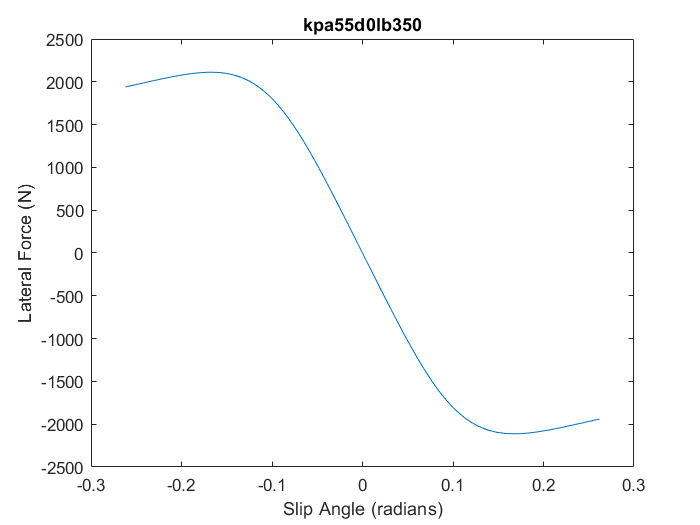

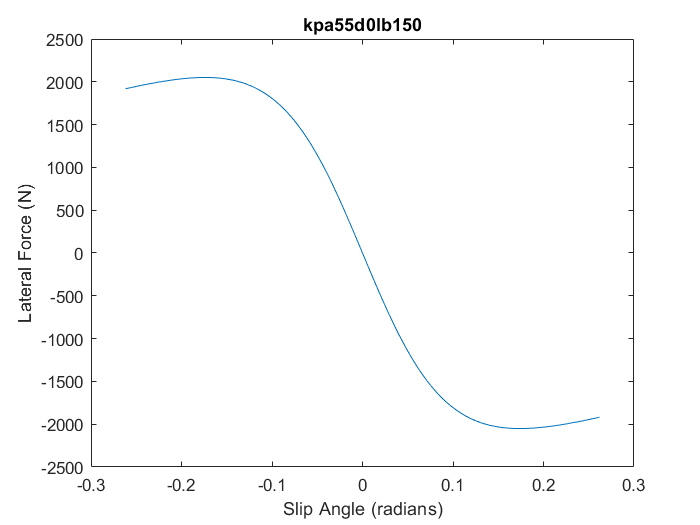

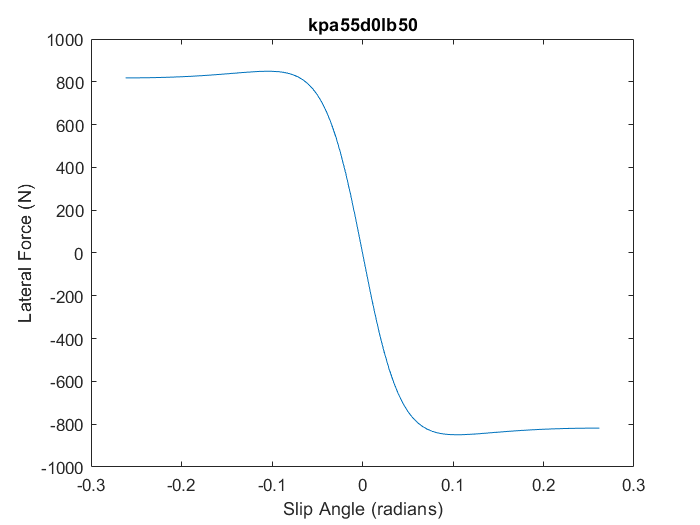

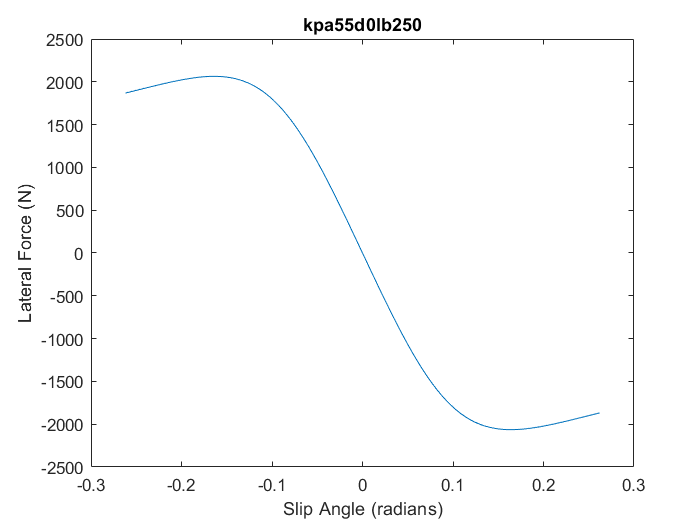

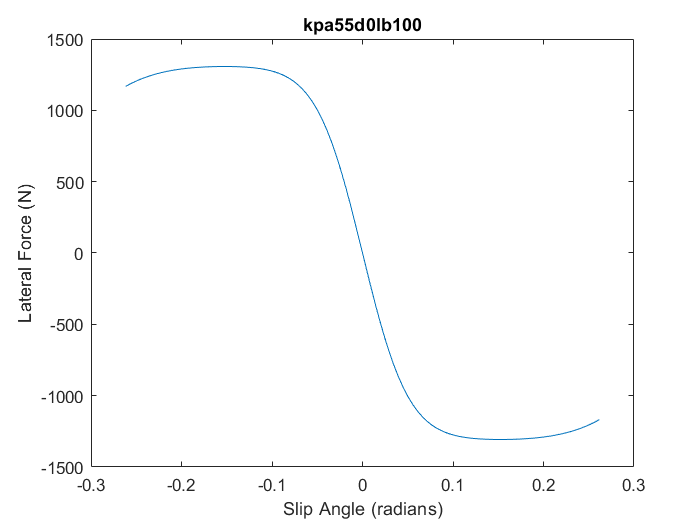

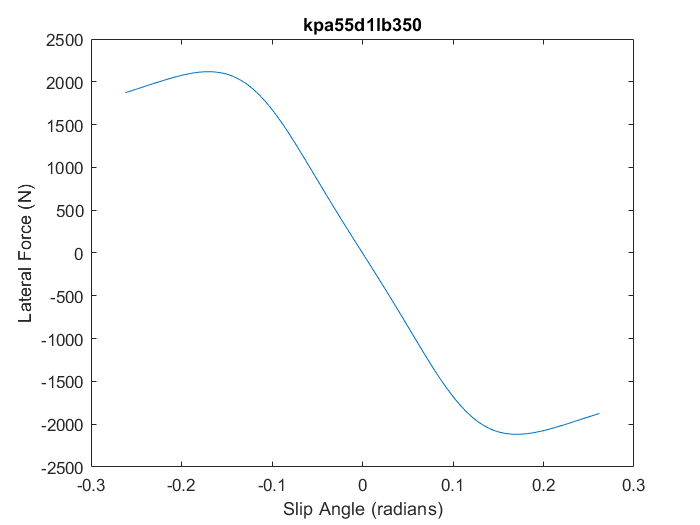

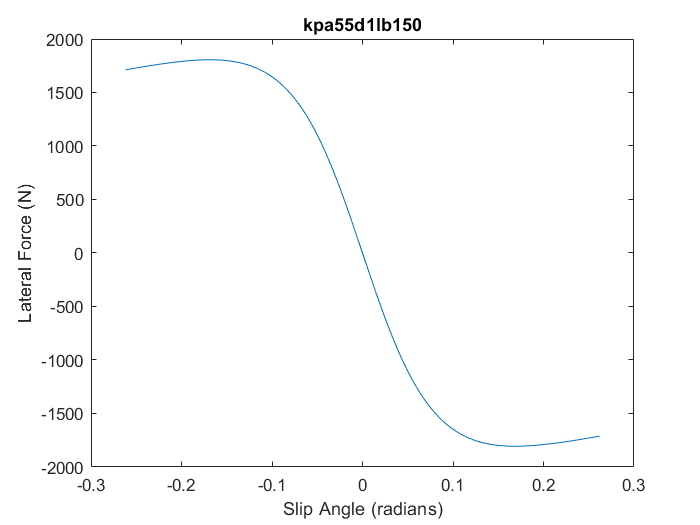

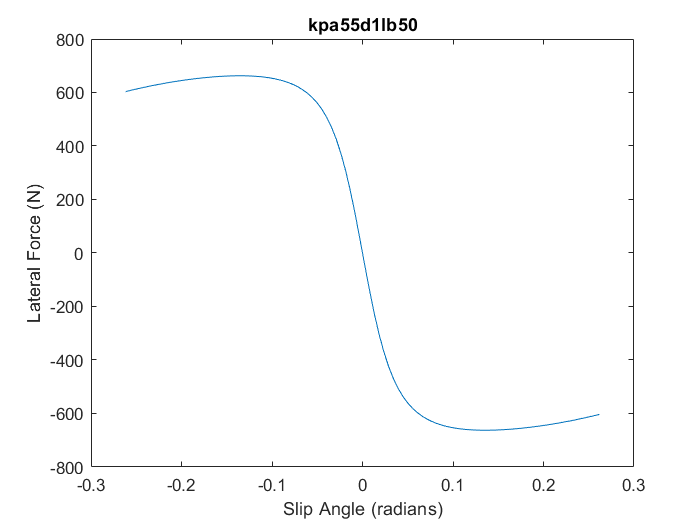

%check that the regressions worked
counter = 1;
for p_index =1:2
    pressure_name_list = ["kpa55","kpa83"];
    for camber_index = 1:5    
        camber_name_list = ["d0","d1","d2","d3","d4"];  
        for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];


            run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
[slipA, Fydata] = plot_regression(fittdata,run_name);
figure(counter)
plot(slipA,Fydata)
title(run_name)
xlabel('Slip Angle (radians)')
ylabel('Lateral Force (N)')
            counter = counter +1;
        end
    end
end


%construct the needed matrices

Cdata = zeros(50,1);
mudata = zeros(50,4);
Edata = zeros(50,3);
Kdata = zeros(50,4);
resp_surf_data = zeros(50,4);
overall_index = 1;

for p_index =1:2
    pressure_name_list = ["kpa55","kpa83"];
    for camber_index = 1:5
        camber_name_list = ["d0","d1","d2","d3","d4"];
        for force_index = 1:5
            force_name_list = ["lb350","lb150","lb50","lb250","lb100"];
run_name = append(pressure_name_list(p_index),camber_name_list(camber_index),force_name_list(force_index));
        
Cdata(overall_index) = fittdata.(run_name).C;
mudata(overall_index,:) = [fittdata.(run_name).dfz,fittdata.(run_name).dpi,fittdata.(run_name).camber,fittdata.(run_name).mu];
Edata(overall_index,:) = [fittdata.(run_name).dfz,fittdata.(run_name).camber,fittdata.(run_name).E];
Kdata(overall_index,:) = [fittdata.(run_name).dpi,fittdata.(run_name).Fz,fittdata.(run_name).camber,fittdata.(run_name).Ky];

resp_surf_data(overall_index,:) = [fittdata.(run_name).dfz,fittdata.(run_name).dpi,fittdata.(run_name).camber,fittdata.(run_name).Fymax];

overall_index = overall_index +1;
        end
    end
end


%regress E
%multiple variable regression code, tweak

FC = Edata(:,1:2)

FC =     0.7299         0
   -0.2586         0
   -0.7529         0
    0.2356         0
   -0.5058         0
    0.7299    1.0000
   -0.2586    1.0000
   -0.7529    1.0000
    0.2356    1.0000
   -0.5058    1.0000


Es = Edata(:,3)

Es =    -1.8430
    0.3713
    1.1188
   -1.1255
    1.6634
   -4.4920
    0.2913
    1.1570
   -1.0956
    1.4692



% mu = (PEY1 + PEY2 * dfz)*(1 + PEY5 *camber^2 - (PEy3 + PEy4 *camber) 
Efunc = @(p,x) (p(1) + p(2).*x(:,1)).*(1 + p(3).*(x(:,2).^2) - (p(4) + p(5).*(x(:,2))))

Efunc = function_handle with value:
    @(p,x)(p(1)+p(2).*x(:,1)).*(1+p(3).*(x(:,2).^2)-(p(4)+p(5).*(x(:,2))))



[B,R,J,CovB] = nlinfit(FC,Es,Efunc,rand(5,1));

BCI = nlparci(B,R,'covar',CovB);

fittdata.Ecoeffs = B;


%check E
p = fittdata.Ecoeffs

p =     0.1908
   -0.3617
    0.0713
   -1.7136
    0.0834



plotEfunc = @(dfz,camber) (p(1) + p(2).*dfz).*(1 + p(3).*(camber.^2) - (p(4) + p(5).*(camber)))

plotEfunc = function_handle with value:
    @(dfz,camber)(p(1)+p(2).*dfz).*(1+p(3).*(camber.^2)-(p(4)+p(5).*(camber)))


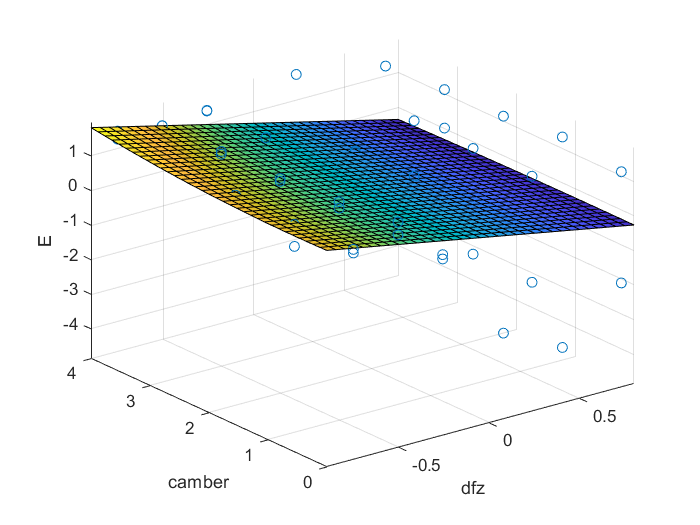


fsurf(plotEfunc,[-.9 .8 0 4])
hold on
plot3(FC(:,1),FC(:,2),Es,'o')
xlabel('dfz')
ylabel('camber')
zlabel('E')
hold off

%regress mu
%multiple variable regression code, tweak

FPC = mudata(:,1:3)

FPC =     0.7299   -0.0833         0
   -0.2586   -0.0833         0
   -0.7529   -0.0833         0
    0.2356   -0.0833         0
   -0.5058   -0.0833         0
    0.7299   -0.0833    1.0000
   -0.2586   -0.0833    1.0000
   -0.7529   -0.0833    1.0000
    0.2356   -0.0833    1.0000
   -0.5058   -0.0833    1.0000


mus = mudata(:,4)

mus =     1.3565
    3.0738
    3.8188
    1.8560
    2.9711
    1.3606
    2.7068
    3.7663
    1.8980
    2.8654



% mu = (PDY1 + PDY2 * dfz)*(1 + PPY3 *dpi + PPY4 * dpi^2)*(1-PDY3*camber^2) 
mufunc = @(p,x) (p(1) + p(2).*x(:,1)).*(1 + p(3).*x(:,2) + p(4).*(x(:,2).^2)).*(1-p(5).*(x(:,3).^2))

mufunc = function_handle with value:
    @(p,x)(p(1)+p(2).*x(:,1)).*(1+p(3).*x(:,2)+p(4).*(x(:,2).^2)).*(1-p(5).*(x(:,3).^2))



[B,R,J,CovB] = nlinfit(FPC,mus,mufunc,rand(5,1));

BCI = nlparci(B,R,'covar',CovB);

fittdata.mucoeffs = B;


kpa_this = -0.0833333333333333

kpa_this = -0.0833

p = fittdata.mucoeffs

p =    -0.4654
    0.6396
   77.3597
 -353.5796
   -0.0016


mufunc_plotFC = @(dfz,camber) (p(1) + p(2).*dfz).*(1 + p(3).*kpa_this + p(4).*(kpa_this.^2)).*(1-p(5).*(camber.^2))

mufunc_plotFC = function_handle with value:
    @(dfz,camber)(p(1)+p(2).*dfz).*(1+p(3).*kpa_this+p(4).*(kpa_this.^2)).*(1-p(5).*(camber.^2))


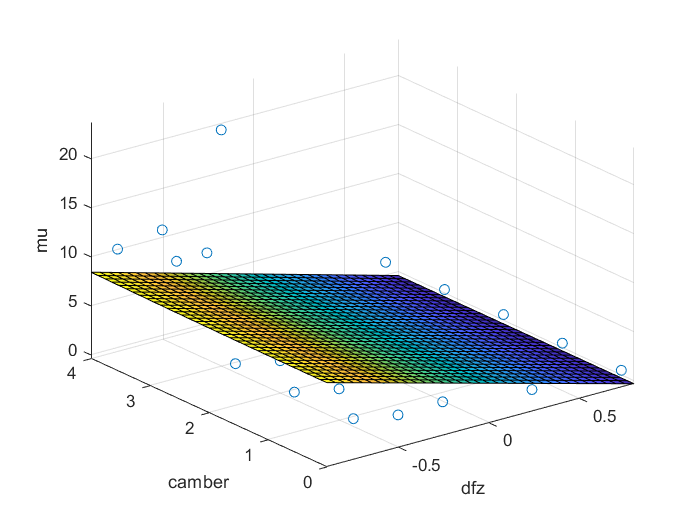


fsurf(mufunc_plotFC,[-.9 .8 0 4])
hold on
plot3(FPC(1:25,1),FPC(1:25,3),mus(1:25),'o')
xlabel('dfz')
ylabel('camber')
zlabel('mu')
hold off


%dfz_this = 
%mufunc_plotPC = @(dpi,camber) (p(1) + p(2).*dfz).*(1 + p(3).*kpa_this + p(4).*(kpa_this.^2)).*(1-p(5).*(camber.^2))


%datafit K and C
PFC = Kdata(:,1:3)

PFC = 	1.0e+03 *

   -0.0001    1.5569         0
   -0.0001    0.6672         0
   -0.0001    0.2224         0
   -0.0001    1.1121         0
   -0.0001    0.4448         0
   -0.0001    1.5569    0.0010
   -0.0001    0.6672    0.0010
   -0.0001    0.2224    0.0010
   -0.0001    1.1121    0.0010
   -0.0001    0.4448    0.0010


Ks = Kdata(:,4)

Ks =     0.0016
   -0.0078
   -0.0116
    0.0027
   -0.0037
    0.0005
   -0.0148
   -0.0192
    0.0020
   -0.0052



% K = Pky1 * FZ0  * (1 + ppy1 *dpi)* sin(pky4 *arctan(Fz/((pky2 + pky5* camber^2)*Fz0*(1+ppy2*dpi) )*(1-pky3*abs(camber)))
Kfunc = @(p,x) (p(1).* FZ0  .* (1 + p(2) .*x(:,1)).* sin(p(3) .*atan(x(:,2)./((p(4) + p(5).* (x(:,3).^2)).*FZ0.*(1+p(6).*x(:,1))))).*(1-p(7).*abs(x(:,3))))

Kfunc = function_handle with value:
    @(p,x)(p(1).*FZ0.*(1+p(2).*x(:,1)).*sin(p(3).*atan(x(:,2)./((p(4)+p(5).*(x(:,3).^2)).*FZ0.*(1+p(6).*x(:,1))))).*(1-p(7).*abs(x(:,3))))




[B,R,J,CovB] = nlinfit(PFC,Ks,Kfunc,rand(7,1));

BCI = nlparci(B,R,'covar',CovB);

fittdata.Kcoeffs = B;
fittdata.Ccoeff = mean(Cdata);


%actually lets try using a response surface, a very complicated one

%dfz,dpi,camber, result

const_p_surfdata = resp_surf_data(1:25,:);
ind_vars = [const_p_surfdata(:,1), const_p_surfdata(:,3)]

ind_vars =     0.7299         0
   -0.2586         0
   -0.7529         0
    0.2356         0
   -0.5058         0
    0.7299    1.0000
   -0.2586    1.0000
   -0.7529    1.0000
    0.2356    1.0000
   -0.5058    1.0000


% const, dfz, camber, dfzcamber, dfz^2, camber^2, dfz camber^2, camber
% dfz^2, camber^3, dfz^3
surfunc = @(p,x) (p(1) + p(2).*x(:,1) + p(3).*x(:,2) + p(4).*x(:,1).*x(:,2) ...
    + p(5).* x(:,1).^2 + p(6).*x(:,2).^2 + p(7).*(x(:,1).^2).*x(:,2) + ...
    p(8).* (x(:,2).^2).*x(:,1) + p(9).* x(:,1).^3 + p(10).*x(:,2).^3 ...
    + p(11).*(x(:,1).^2).*(x(:,2).^2))

surfunc = function_handle with value:
    @(p,x)(p(1)+p(2).*x(:,1)+p(3).*x(:,2)+p(4).*x(:,1).*x(:,2)+p(5).*x(:,1).^2+p(6).*x(:,2).^2+p(7).*(x(:,1).^2).*x(:,2)+p(8).*(x(:,2).^2).*x(:,1)+p(9).*x(:,1).^3+p(10).*x(:,2).^3+p(11).*(x(:,1).^2).*(x(:,2).^2))



[B,R,J,CovB] = nlinfit(ind_vars,const_p_surfdata(:,4),surfunc,rand(11,1));

surfcoeffs = B;

const_p_surfdata2 = resp_surf_data(26:50,:);
ind_vars2 = [const_p_surfdata(:,1), const_p_surfdata(:,3)]

ind_vars2 =     0.7299         0
   -0.2586         0
   -0.7529         0
    0.2356         0
   -0.5058         0
    0.7299    1.0000
   -0.2586    1.0000
   -0.7529    1.0000
    0.2356    1.0000
   -0.5058    1.0000


% const, dfz, camber, dfzcamber, dfz^2, camber^2, dfz camber^2, camber
% dfz^2, camber^3, dfz^3
surfunc = @(p,x) (p(1) + p(2).*x(:,1) + p(3).*x(:,2) + p(4).*x(:,1).*x(:,2) ...
    + p(5).* x(:,1).^2 + p(6).*x(:,2).^2 + p(7).*(x(:,1).^2).*x(:,2) + ...
    p(8).* (x(:,2).^2).*x(:,1) + p(9).* x(:,1).^3 + p(10).*x(:,2).^3 ...
    + p(11).*(x(:,1).^2).*(x(:,2).^2))

surfunc = function_handle with value:
    @(p,x)(p(1)+p(2).*x(:,1)+p(3).*x(:,2)+p(4).*x(:,1).*x(:,2)+p(5).*x(:,1).^2+p(6).*x(:,2).^2+p(7).*(x(:,1).^2).*x(:,2)+p(8).*(x(:,2).^2).*x(:,1)+p(9).*x(:,1).^3+p(10).*x(:,2).^3+p(11).*(x(:,1).^2).*(x(:,2).^2))



[B,R,J,CovB] = nlinfit(ind_vars,const_p_surfdata2(:,4),surfunc,rand(11,1));

surfcoeffs83 = B;

p = surfcoeffs

p = 	1.0e+03 *

    2.0484
    0.7346
   -0.1436
    0.2096
   -1.0998
    0.0831
   -0.0212
   -0.0168
    0.0462
   -0.0133



surfuncplot = @(dfz,camber) (p(1) + p(2).*dfz + p(3).*camber + p(4).*dfz.*camber ...
    + p(5).* dfz.^2 + p(6).*camber.^2 + p(7).*(dfz.^2).*camber + ...
    p(8).* (camber.^2).*dfz + p(9).* dfz.^3 + p(10).*camber.^3 + p(11).* camber.^2 .* dfz.^2)

surfuncplot = function_handle with value:
    @(dfz,camber)(p(1)+p(2).*dfz+p(3).*camber+p(4).*dfz.*camber+p(5).*dfz.^2+p(6).*camber.^2+p(7).*(dfz.^2).*camber+p(8).*(camber.^2).*dfz+p(9).*dfz.^3+p(10).*camber.^3+p(11).*camber.^2.*dfz.^2)


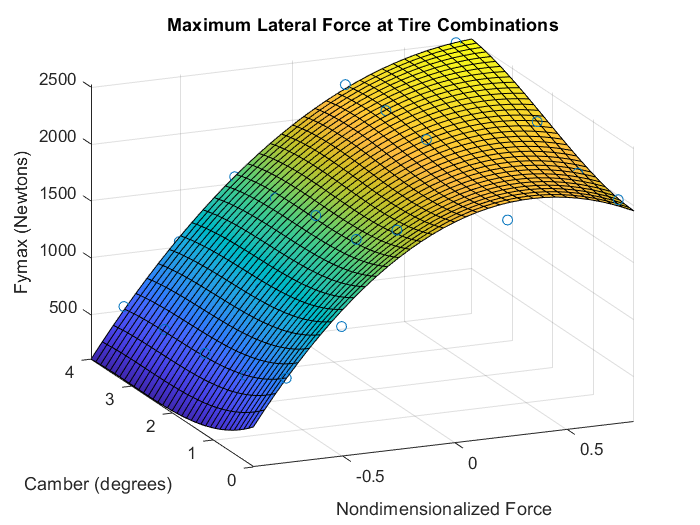



fsurf(surfuncplot,[-.9 .8 0 4])
hold on
plot3(ind_vars(:,1),ind_vars(:,2),const_p_surfdata(:,4),'o')
title('Maximum Lateral Force at Tire Combinations')
xlabel('Nondimensionalized Force')
ylabel('Camber (degrees)')
zlabel('Fymax (Newtons)')
hold off


p = surfcoeffs83;
surfuncplot = @(dfz,camber) (p(1) + p(2).*dfz + p(3).*camber + p(4).*dfz.*camber ...
    + p(5).* dfz.^2 + p(6).*camber.^2 + p(7).*(dfz.^2).*camber + ...
    p(8).* (camber.^2).*dfz + p(9).* dfz.^3 + p(10).*camber.^3 + p(11).* camber.^2 .* dfz.^2)

surfuncplot = function_handle with value:
    @(dfz,camber)(p(1)+p(2).*dfz+p(3).*camber+p(4).*dfz.*camber+p(5).*dfz.^2+p(6).*camber.^2+p(7).*(dfz.^2).*camber+p(8).*(camber.^2).*dfz+p(9).*dfz.^3+p(10).*camber.^3+p(11).*camber.^2.*dfz.^2)


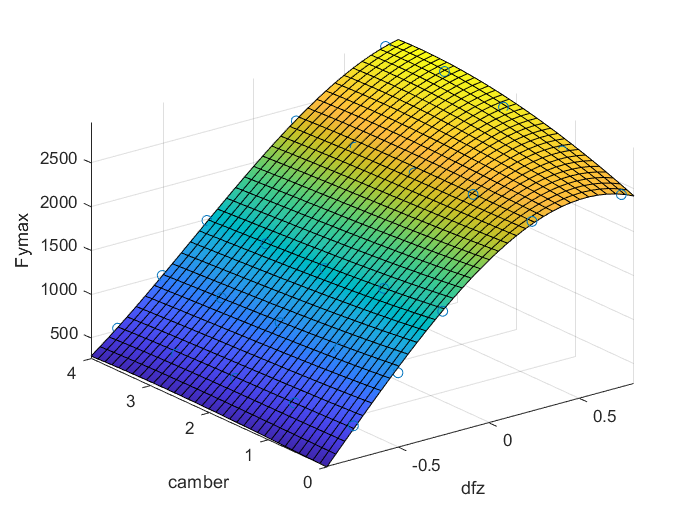


fsurf(surfuncplot,[-.9 .8 0 4])
hold on
plot3(ind_vars2(:,1),ind_vars2(:,2),const_p_surfdata2(:,4),'o')
xlabel('dfz')
ylabel('camber')
zlabel('Fymax')
hold off

pause
[D,S] = xlsread('Data_Source.xlsx');
EPT = D(:,1:3);
tauv = D(:,4);
% tau(i) = ai * (p^bi) * (T^ci)  * EXP(di / T) * (phi^ei)
taufcn = @(b,x) b(1) * x(:,2).^b(2) .* x(:,3).^b(3) .* exp(b(4)./x(:,3)) .* x(:,1).^b(5);
[B,R,J,CovB] = nlinfit(EPT,tauv,taufcn,rand(5,1));
BCI = nlparci(B,R,'covar',CovB);